# [Solutions] Two-site energy variance

Author: [Seung-Sup Lee](https://cqm.snu.ac.kr)

## Solution to Exercise (a): Complete the function for the two-site energy variance

The complete version is uploaded as `DMRG/varE_2site.m`. Compare with your version!

## Solution to Exercise (b): Extrapolate the ground-state energy as a function of the two-site variance

We consider eight different values of `Nkeep` = (20:20:160).

clear

% system parameters
J = -1; % coupling strength
L = 40; % number of sites in a chain

% DMRG parameter
Nkeep = (20:20:160);
Nsweep = 4; % number of pairs of left+right sweeps

% Local operators
[S,I] = getLocalSpace('Spin',1/2);

% % MPO formulation of Hamiltonian
% Hamiltonian tensor for each chain site
Hloc = cell(4,4);
Hloc(:) = {zeros(size(I))};
Hloc{1,1} = I;
Hloc{2,1} = S(:,:,1);
Hloc{3,1} = S(:,:,3);
Hloc{4,2} = J*S(:,:,1)';
Hloc{4,3} = J*S(:,:,3)';
Hloc{end,end} = I;
Hloc = cell2mat(reshape(Hloc,[1 1 size(Hloc,1) size(Hloc,2)]));

% full chain
Hs = cell(1,L);
Hs(:) = {Hloc};
Hs{1} = Hs{1}(:,:,end,:); % choose the last components of the left leg
Hs{end} = Hs{end}(:,:,:,1); % choose the first components of the right leg

Minit = cell(1,L);

E0s = zeros(size(Nkeep));
varEs = zeros(size(Nkeep));

For each value of `Nkeep`, we perform the iterative diagonalization to construct the initial MPS.

for itk = (1:numel(Nkeep))
    % tensors for the vaccum (i.e., dummy leg)
    Hprev = 1; % initialize Hamiltonian with 1, as we will use MPO
    Aprev = 1; % identity tensor for the dummy leg
    
    for itN = (1:L)
        % add new site
        Anow = getIdentity(Aprev,2,I,2,[1 3 2]);
        Hnow = updateLeft(Hprev,3,Anow,Hs{itN},4,Anow);
    
        Hmat = Hnow(:,:,1);
        [V,D] = eig((Hmat+Hmat')/2);
        [D,ids] = sort(diag(D),'ascend');
        if itN < L
            Ntr = min([numel(D);Nkeep(itk)]);
        else
            Ntr = 1;
        end
        V = V(:,ids(1:Ntr));
        
        Anow = contract(Anow,3,2,V,2,1,[1 3 2]);
    
        Minit{itN} = Anow;
        
        Hprev = contract(Hnow,3,2,V,2,1);
        Hprev = contract(V',2,2,Hprev,3,1,[1 3 2]);
        Aprev = Anow;
    end
    
    [M,E0s(itk),Eiter] = DMRG_GS_1site(Minit,Hs,Nkeep(itk),Nsweep);
    varEs(itk) = varE_2site(M,Hs);
end

I cleared the log message since it's too long. The calculation result can be summarized as:

for itk = (1:numel(Nkeep))
    disp(['Nkeep = ',sprintf('%i',Nkeep(itk)),', E0 = ', ...
        sprintf('%.16f',E0s(itk)),', varE = ',sprintf('%.16f',varEs(itk))]);
end

Nkeep = 20, E0 = -12.5538708557288849, varE = 0.0000429441303004
Nkeep = 40, E0 = -12.5538983621076738, varE = 0.0000004268844950
Nkeep = 60, E0 = -12.5538985539350207, varE = 0.0000000041831295
Nkeep = 80, E0 = -12.5538985556585345, varE = 0.0000000003624229
Nkeep = 100, E0 = -12.5538985558001848, varE = 0.0000000000256240
Nkeep = 120, E0 = -12.5538985558106688, varE = 0.0000000000027989
Nkeep = 140, E0 = -12.5538985558116796, varE = 0.0000000000006278
Nkeep = 160, E0 = -12.5538985558118288, varE = 0.0000000000001100


Since we have the exact result of the ground-state energy, we can plot the error of the ground-state energy (with respect to the exact result) versus the two-site variance.

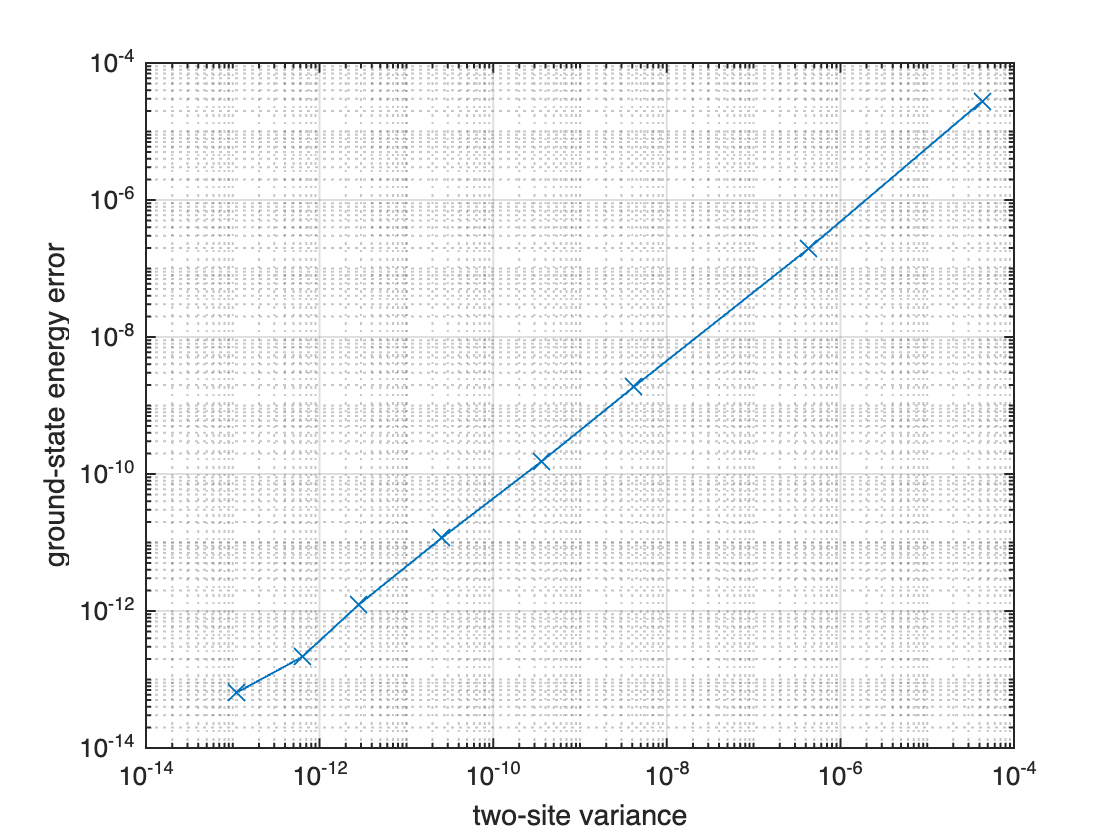

E0_exact = (-J)*(0.5 - (1/2/sin(pi/2/(L+1)))); % exact value
figure;
plot(varEs,E0s-E0_exact,'-x','LineWidth',1,'MarkerSize',12);
set(gca,'XScale','log','YScale','log','LineWidth',1,'FontSize',13);
grid on;
xlabel('two-site variance');
ylabel('ground-state energy error');

The energy vs. variance shows a nice linear dependence, while there are weak kinks near the smallest variance (since the error and the variance have reached the numerical precision limit) and neaer the largest variance (since the bond dimensions are not big enough to be fully on the scaling regime).

Let's perform the linear regression, omitting the data points for the two smallest `Nkeep`'s.

p = polyfit(varEs(3:8),E0s(3:8),1);
disp(['Extrapolated GS energy = ',sprintf('%.16g',p(2))]);

Extrapolated GS energy = -12.55389855581361


disp(['Error of the extrapolated value = ',sprintf('%.4g',p(2)-E0_exact)]);

Error of the extrapolated value = -1.716e-12


We see that the extrapolation well agrees with the exact result.

## Solution to Exercise (c): Hubbard chain

Let's define the parameters and operators to use.

clear

% system parameters
U = 8; % interaction strength
mu = U/2; % chemical potential
t = 1; % hopping amplitude
L = 30; % number of sites in a chain

% Local operators
[F,Z,S,I] = getLocalSpace('FermionS');

% Particle number operators
NF = contract(conj(F(:,:,1)),3,[1 3],F(:,:,1),3,[1 3]) + ...
     contract(conj(F(:,:,2)),3,[1 3],F(:,:,2),3,[1 3]);

% % MPO formulation of Hamiltonian
% Hamiltonian tensor for each chain site
Hloc = cell(6,6);
Hloc(:) = {zeros(size(I))};
Hloc{1,1} = I;
Hloc{2,1} = Z*F(:,:,1);
Hloc{3,1} = Z*F(:,:,2);
Hloc{4,1} = Hloc{2,1}';
Hloc{5,1} = Hloc{3,1}';
Hloc{6,1} = (U/2)*NF*(NF-I) - mu*NF;
Hloc{6,2} = -t*F(:,:,1)';
Hloc{6,3} = -t*F(:,:,2)';
Hloc{6,4} = -t*F(:,:,1);
Hloc{6,5} = -t*F(:,:,2);
Hloc{6,6} = I;
Hloc = cell2mat(reshape(Hloc,[1 1 size(Hloc,1) size(Hloc,2)]));

% full chain
Hs = cell(1,L);
Hs(:) = {Hloc};
Hs{1} = Hs{1}(:,:,end,:); % choose the last components of the left leg
Hs{end} = Hs{end}(:,:,:,1); % choose the first components of the right leg

Note that the fermionic sign operator `Z` is necessary in the construction of the MPO Hamiltonian.

We will perform the DMRG ground-state search in the increasing order of `Nkeep` = (100:50:400), where the result MPS from the previous iteration is used as the input to the next iteration. We use a random MPS as the initial state for the first iteration.

% DMRG parameters
Nkeep = (100:50:400);
Nsweep = 5; % number of pairs of left+right sweeps

Minit = cell(1,L);
for itN = (1:L)
    if itN == 1
        Minit{itN} = rand(1,Nkeep(1),size(I,2));
    elseif itN == L
        Minit{itN} = rand(Nkeep(1),1,size(I,2));
    else
        Minit{itN} = rand(Nkeep(1),Nkeep(1),size(I,2));
    end
end

E0s = zeros(1,numel(Nkeep));
varEs = zeros(1,numel(Nkeep));
for itk = (1:numel(Nkeep))
    [Minit,E0s(itk),Eiter] = DMRG_GS_2site(Minit,Hs,Nkeep(itk),Nsweep);
    varEs(itk) = varE_2site(Minit,Hs);
end

I cleared the log message since it's too long.

for itk = (1:numel(Nkeep))
    disp(['Nkeep = ',sprintf('%i',Nkeep(itk)),', E0 = ', ...
        sprintf('%.16f',E0s(itk)),', varE = ',sprintf('%.16f',varEs(itk))]);
end

Nkeep = 100, E0 = -129.6199589521511655, varE = 0.0032179999858300
Nkeep = 150, E0 = -129.6204748975554821, varE = 0.0000002539200819
Nkeep = 200, E0 = -129.6204749194528461, varE = 0.0000000189649706
Nkeep = 250, E0 = -129.6204749208879434, varE = 0.0000000055893979
Nkeep = 300, E0 = -129.6204749211981664, varE = 0.0000000014051735
Nkeep = 350, E0 = -129.6204749212677996, varE = 0.0000000004327037
Nkeep = 400, E0 = -129.6204749212902243, varE = 0.0000000001260781


Let's analyze how the ground-state energy scales with the two-site variance.

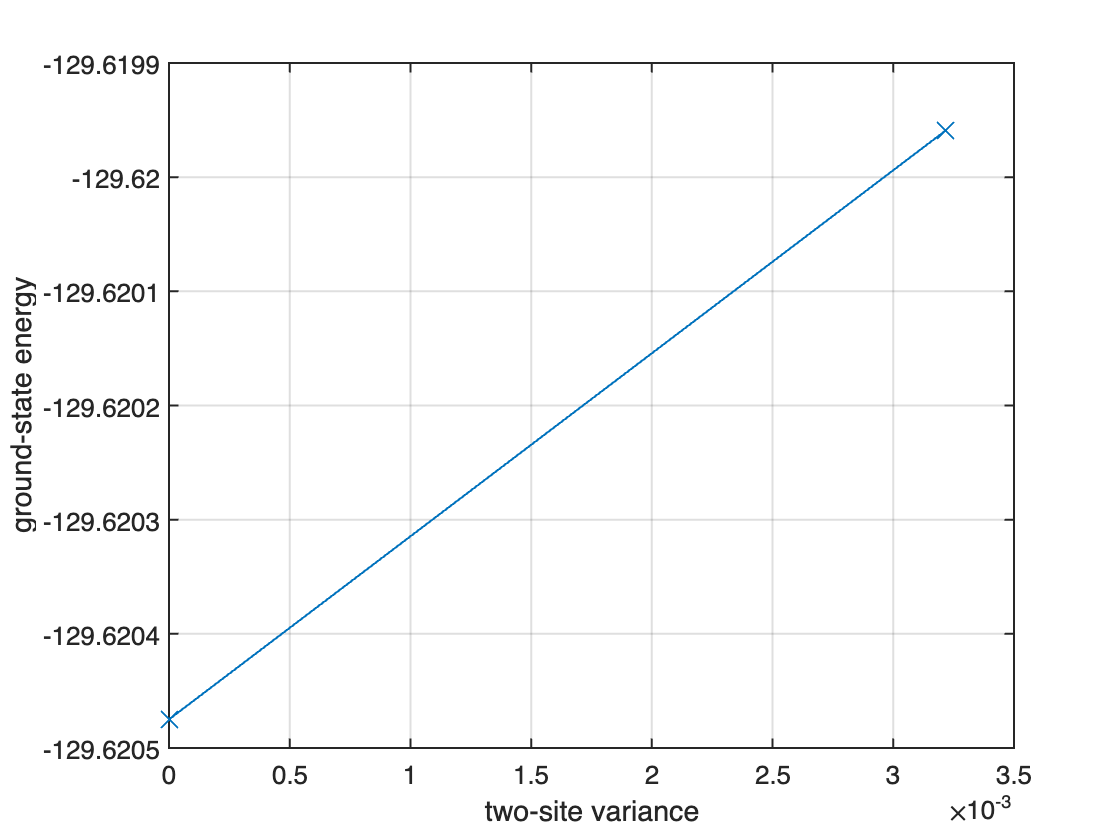

figure;
plot(varEs,E0s,'-x','LineWidth',1,'MarkerSize',12);
set(gca,'LineWidth',1,'FontSize',13);
grid on;
xlabel('two-site variance');
ylabel('ground-state energy');

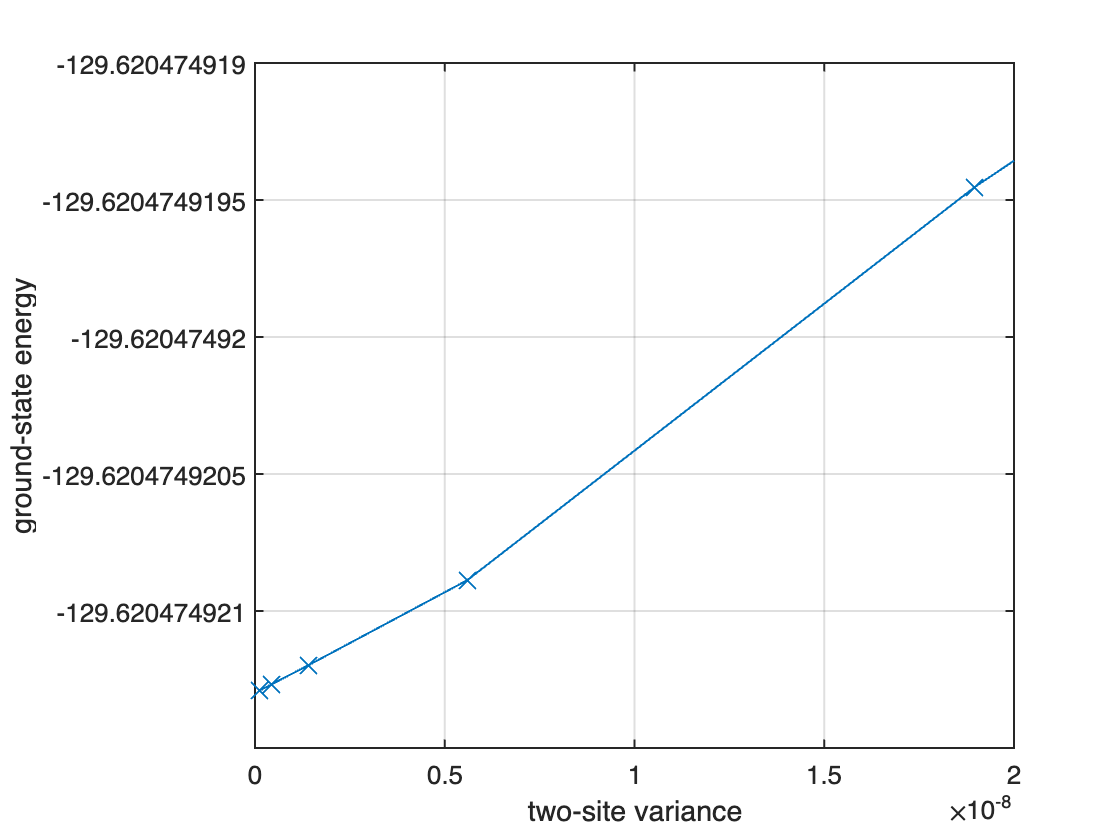

figure;
plot(varEs,E0s,'-x','LineWidth',1,'MarkerSize',12);
set(gca,'LineWidth',1,'FontSize',13);
grid on;
xlabel('two-site variance');
ylabel('ground-state energy');
xlim([0 2e-8]);

We see that the ground-state energy vs. two-site variance shows a nice linear scaling. 

Let's perform the linear regression, omitting the data points for the three smallest `Nkeep`'s.

p = polyfit(varEs(4:end),E0s(4:end),1);
disp(['Extrapolated GS energy = ',sprintf('%.16g',p(2))]);

Extrapolated GS energy = -129.6204749213002
